# **Practical: Markov Chains**

### **Assignment 3 - PageRank I (35) **

**Notebook info:** Due to a mixture of code and analysis being required for many of the solutions, please insert the code blocks where you feel is necessary to answer the question. Graphs and images can either be inserted as jpg's in the .mlx file, or save this file as a LateX file and insert the images through Overleaf. Otherwise, include the images in a .zip and make sure you clearly indicate which images you are referring to in your text. 

Additionally, functions cannot be defined and run through normal Live Scripts like Jupyter lab (terribly sorry, Matlab is quirky like that), so it is better to define the function in a .m or Live Function (New > Live Function) and call the function in your script where you wish to use it. If you wish to be safe, provide the .m files in the zip, so we have everything we need to grade you in case of ambiguity.

The function *pagerank(U,G,p)* of the EXM toolbox computes PageRanks of a web network, where

- *U* = a cell array of n strings, the URLs of the nodes;

- *G* = an n-by-n sparse connectivity matrix with *G(i,j)=1* if node j is linked to node *i* and *G(i,j)=0* otherwise;

- *p* is the probability that the random surfer follows a link (default is .85) In pagerank the PageRanks are computed by solving a sparse linear system. The function then plots a bar graph of PageRanks and prints the dominant URLs.

In *pagerank* the PageRanks are computed by solving a sparse linear system. The function then plots a bar graph of PageRanks and prints the dominant URLs.

In the file *Practical_MarkovChains.zip* in Nestor an example dataset *harvard500-2018.mat* is available that was generated by accessing the home page of Harvard University in February 2018, resulting in a 500-by-500 test case.

- (5pt) Create and execute a Matlab program with the following commands: 

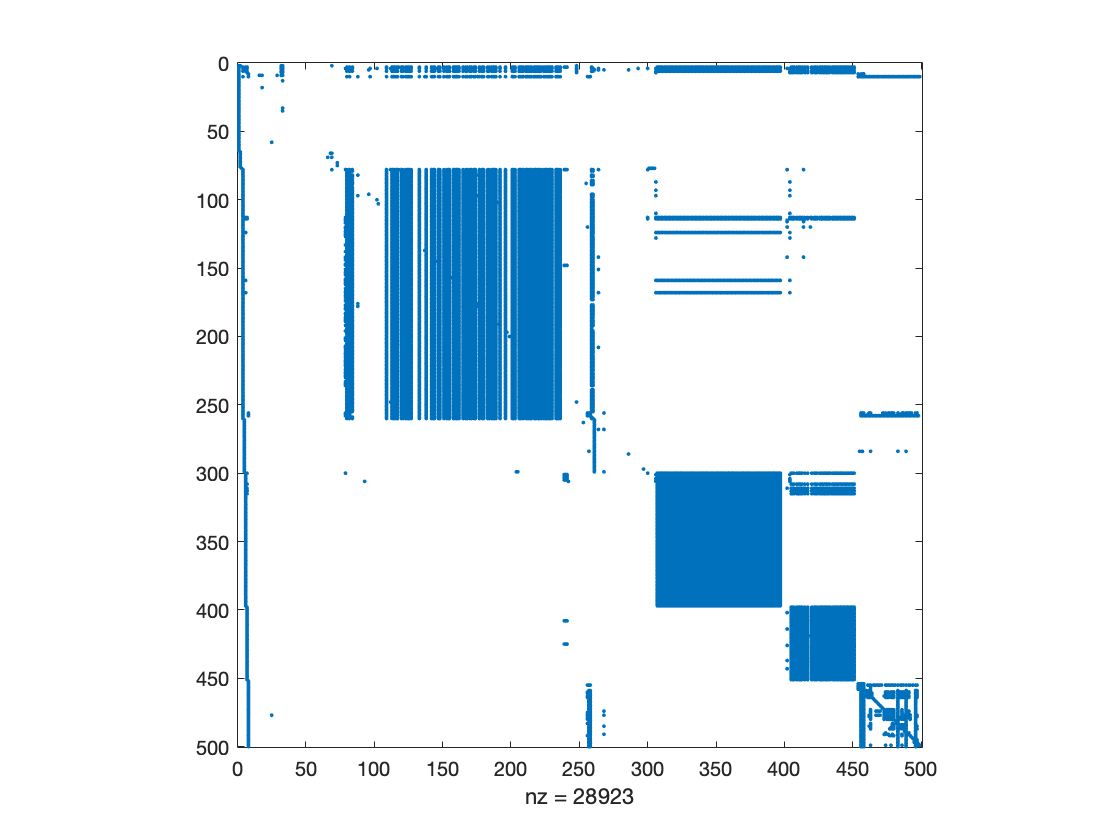

load harvard500-2018;
spy(G);

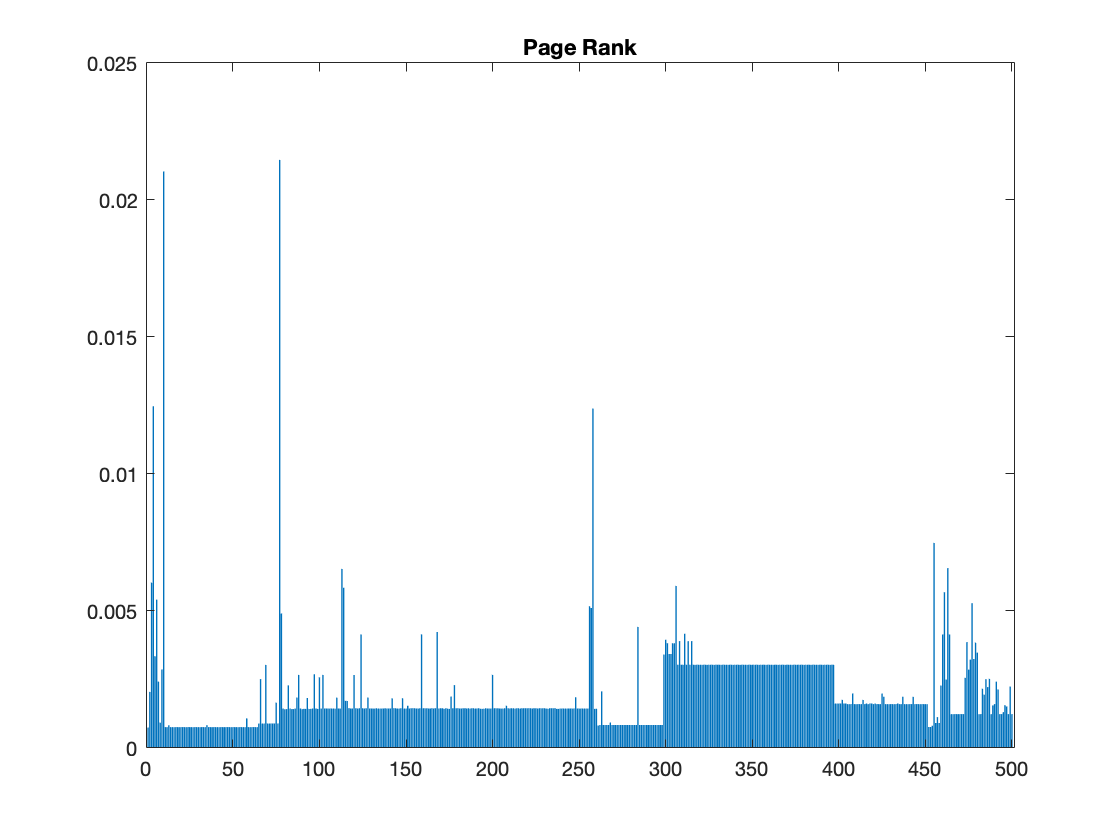

     page-rank  in  out  url
  77   0.0215    6    0  http://dublincore.org/documents/abstract-model/).  As of December 2007, the DCMI Usage Board is seeking a way to express this intention with a formal range declaration.
  10   0.0210  134    0  http://schema.org
   4   0.0125  230  186  http://xmlns.com/foaf/0.1
 258   0.0124  126   46  http://schema.org/CreativeWork
 455   0.0075   36    2  http://schema.org/Text
 463   0.0066   29   26  http://schema.org/Event
 113   0.0065  218  186  http://xmlns.com/foaf/0.1/Agent
   3   0.0060  221    1  http://purl.org/dc/terms
 306   0.0059   95   16  http://rdfs.org/sioc/spec
 114   0.0058  217  186  http://xmlns.com/foaf/0.1/Document
 461   0.0057   27    7  http://schema.org/Thing
   6   0.0054  219  105  http://rdfs.org/sioc/ns#
 477   0.0053   31   16  http://schema.org/Organization
 256   0.0052  106   17  http://schema.org/Person
 257   0.0051  104   45  http://schema.org/ImageObject


pagerank(U, G);

These commands load the *harvard500-2018* dataset, produce a spy plot to check the nonzero structure of the connectivity, and then compute the PageRanks, producing a bar graph and printing the dominant URLs. Put the spy plot and the list with the most highly ranked pages (top 10) in your report (or insert them below). 

Done in the report.

- (15pt) Write a Matlab function *A=ISClinks(U,G)* to search pages for the harvard dataset that only have one outgoing and incoming node (excluding self-referential links). Identify the organizations.

                The function can be found in the file ISClinks.m

- (15pt) A web connectivity matrix *G* has *gij = 1* if it is possible to get to page *i* from page *j *with one click. If you multiply the matrix by itself, the entries of the matrix *G^2* count the number of different paths of length two to page *i *from page *j*. The matrix power *G^p* shows the number of paths of length *p*.

(a) For the* harvard500-2018* data set, find the power *p* where the number of nonzeros stops increasing. In other words, for* i > p*, *nnz(G^i)* is equal to *nnz(G^p)*.

The solution can be found in the file part1.m

(b) What fraction of the entries in *G^p* are nonzero? Indicate how you compute it.

We have indicated it in the file part1.m

(c) Use subplot and spy to show the nonzeros in the successive powers:

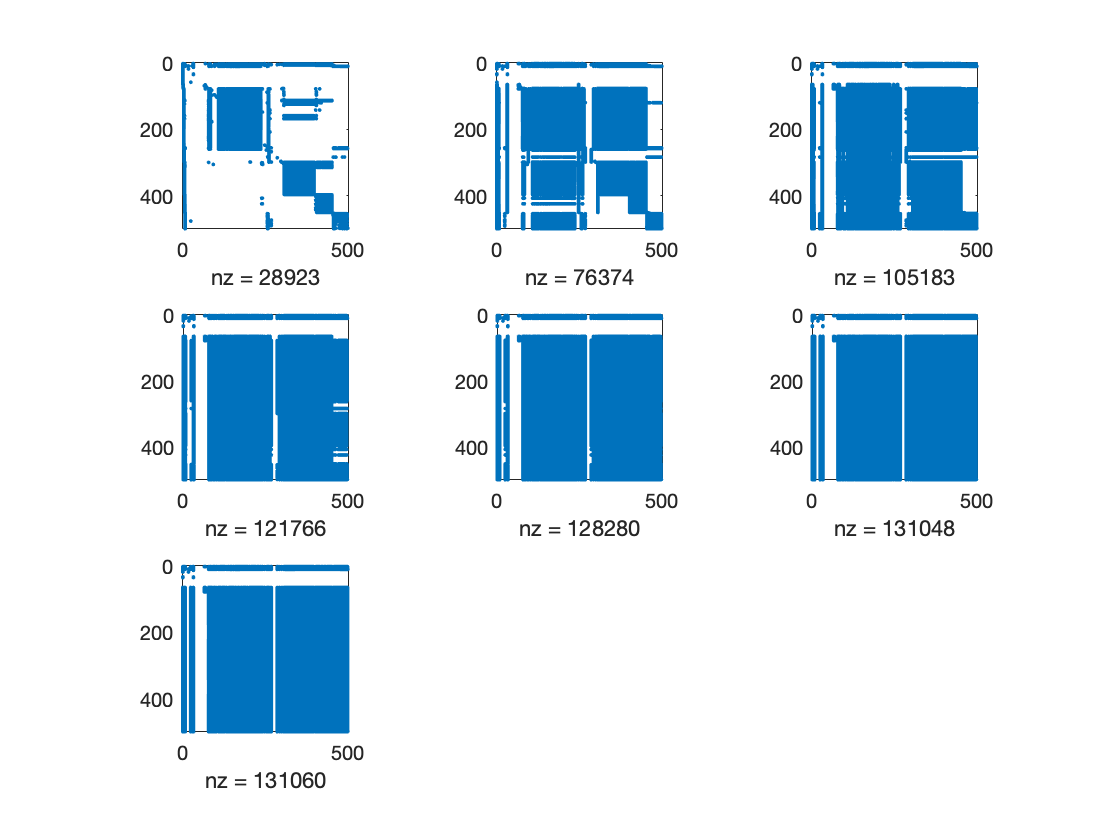

for i = 1:p
subplot(3,3,i)
spy(G^i)
end

The analysis can be found in the pdf file we provided.

### Assignment 4 - PageRank II (65)

Figure 1 is an example graph of what could be a tiny six-node subset of the Web. Nodes represents web pages and edges represent links between web pages. In this assignment you will create your own Matlab program that computes the PageRanks and apply it to the tiny web of Fig. [1.](javascript:void(0))

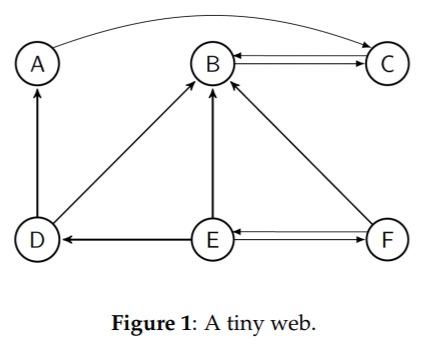

- (10pt) What is the connectivity matrix *G* of the tiny network? (Order the nodes according to alphabetical order of the node labels.)

            The matrix can be found in the report PDF file.

- (10pt) The Markov matrix of an arbitrary network *G* is defined by:

Here *Gij* are the elements of the connectivity matrix* G* of the network, *p* is the probability that a surfer follows a link on the network, *n* is the size of the matrix *G*, *c_j* is the sum of the *j*-th column of *G* (the out-degree of the *j*-th node) and *δ = (1 − p)/n* is the probability that a surfer chooses a random page. 

Write a Matlab function *A=ISCmarkov_matrix(p,G)* that computes the Markov matrix of a network *G* with surfing probability* p*. 

    The function can be found in the file ISCmarkov_matrix.m

Create a Matlab test script *ISCpagerank_test1*. Put the matrix *G* in it. Also define the default value p=0.85 in your script. Add the statement 

A = ISCmarkov_matrix(p,G);

Unrecognized function or variable 'ISCmarkov_matrix'.

to your test script *ISCpagerank_test1*, run the script in Matlab.

-  (20pt) Implement the power method for finding the equilibrium distribution of the Markov chain in full (non-sparse) form, by creating a Matlab function:

[x,iter] = ISCmarkov(A,tol,maxiter)

that repeatedly executes the equation

x_new = Ax

starting from a uniform distribution *x(i)=1/n* for all *i*. The iteration should terminate when successive vectors *x* and *x_new* agree within a specified tolerance* tol *or when a maximum number of iterations *maxiter* is reached. The function should return the vector *x* at termination (the equilibrium distribution), and *iter*, the actual number of iterations used. For comparing vectors x and x_new you can use the Matlab function *norm(abs(x-x_new))*.

Test your function *ISCmarkov* on a 2 × 2 matrix *A* for which the equilibrium vector *x* is known and verify that the result is correct up to four decimal places. To find an example of *A,* please refer to the equation 3.11 given in Chapter 3, Section 3 in the book. Choose the parameters *tol* and *maxiter* appropriately.

The function can be found in the file ISCmarkov.m

- (10pt) Add the settings of the parameters tol and maxiter found in the previous question to your test script *ISCpagerank_test1*, followed by the statement

[x,iter] = ISCmarkov(A,tol,maxiter);

that computes the vector *x* and the number iter of iterations used, and run your script in Matlab. Add Matlab code that reorders the elements of the solution vector *x* to obtain the PageRanks.

    Done in the file ISCpagerank_test1.m

- (15pt) Create *ISCpagerank2(G,p)* by modifying the Matlab function* pagerank(U,G,p)* from the EXM toolbox so that it just computes the PageRanks, but does not do any plotting or printing. Then create a test script *ISCpagerank_test2*. Again, first put the matrix *G* and the default value p=0.85 in your script, and then add a call to *ISCpagerank2(G,p)* to compute the PageRanks. Do the results of *ISCpagerank_test1* and *ISCpagerank_test2 agree?* If not, adjust the parameters *tol* and *maxiter* for the function *ISCmarkov*.

        Files with the solution : ISCpagerank2.m and test file : ISCpagerank_test2.m

**Hand in:**

- your Matlab programs

- *ISClinks.m,*

- *ISCmarkov_matrix.m,*

- *ISCmarkov.m,*

- *ISCpagerank_test1.m*

- *ISCpagerank2.m*

- *ISCpagerank_test2.m.*

- a concise report in PDF format (generated by LaTeX), following the guidelines in the Introduction of the lab manual, in which:

- you describe, for each part of every assignment, how you arrived at the solution

- you answer all the questions posed in the assignments,

- you add listings of your Matlab programs in an appendix

Write at the top of the first page of your report: **“Introduction to Scientific Computing, Practical Markov Chains”**, followed by your names, student numbers, and the date when you hand in the report.

Since you work in pairs, you need to include information in your report about your individual contributions. For each assignment, indicate the contribution (mention percentages) for each of you in terms of tasks performed (program design, program implementation, answering questions posed, writing the report). All files have to be handed in as **a single archive** (called *YourName.zip*), where “YourName” is the concatenation of your last names. See Nestor for the address to which you have to send the archive.